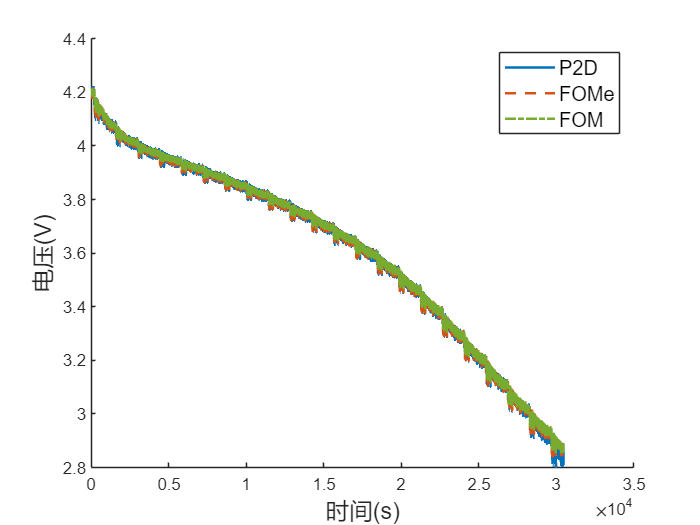

clear;
load fuds.txt;
load dyn_fuds.txt;
t_fuds=dyn_fuds(end,1);
I_fuds=fuds(1:t_fuds,2)*17.5;

v_fuds=dyn_fuds(:,2);
v_fome=dyn_fome(I_fuds);
v_fom=dyn_fom(I_fuds);

figure(1);
clf;
hold on;
plot(v_fuds,LineWidth=1.5);
plot(v_fome,LineWidth=1.5,LineStyle="--");
plot(v_fom,LineWidth=1.5,Color="#77AC30",LineStyle="-.");
xlabel('时间(s)','fontsize',14);
ylabel('电压(V)','fontsize',14);
legend('P2D','FOMe','FOM','fontsize',12);

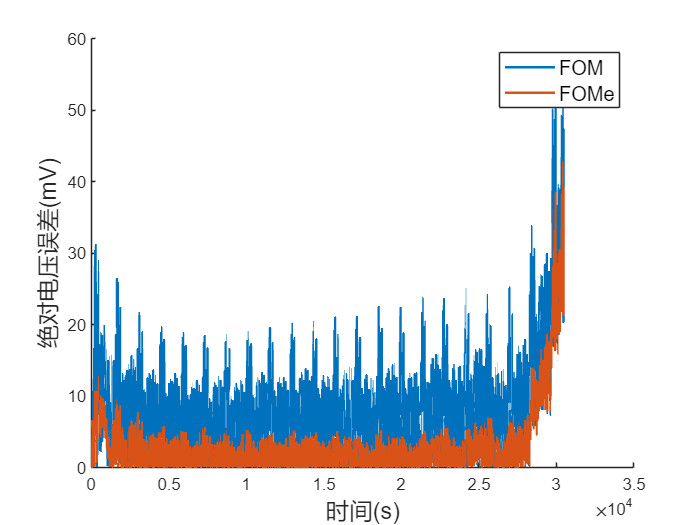

erro(1,1)=RMSE(v_fome,v_fuds)*1000;erro(2,1)=MAPE(v_fome,v_fuds);
erro(1,2)=RMSE(v_fom,v_fuds)*1000;erro(2,2)=MAPE(v_fom,v_fuds);

fome_abs=abs(v_fuds-v_fome)*1000;
fom_abs=abs(v_fuds-v_fom)*1000;

figure(2);
clf;
hold on;
plot(fom_abs,LineWidth=1.5);
plot(fome_abs,LineWidth=1.5);
xlabel('时间(s)','fontsize',14);
ylabel('绝对电压误差(mV)','fontsize',14);
legend('FOM','FOMe','fontsize',12);